Basic scenario/map setup

scenario = robotScenario(UpdateRate=5);

floorColor = [1 0 0.5];
addMesh(scenario, "Plane", Position=[4.5 2.5 0], Size=[9 5], Color=floorColor);

wallHeight = 1;
wallWidth = 0.05;
wallColor = [1 1 0.8157];

Add outer walls to the map

addMesh(scenario, "Box", Position=[0+wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 5-wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[9-wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 0+wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Add inner walls to the map

addMesh(scenario, "Box", Position=[1, 2, wallHeight/2], ...
    Size=[2, 4, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4, 1.5, wallHeight/2], ...
    Size=[2, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6, 3.5, wallHeight/2], ...
    Size=[4, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6.5, 2, wallHeight/2], ...
    Size=[1, 2, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[7.5, 1.5, wallHeight/2], ...
    Size=[1, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Visualize the map

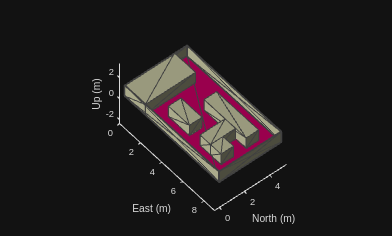

show3D(scenario);
lightangle(-45, 30);
view(50, 50);

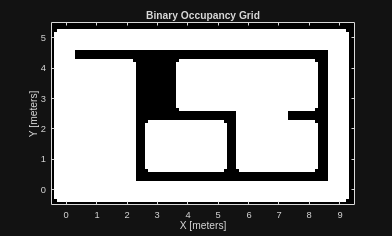

map = binaryOccupancyMap(scenario, GridOriginInLocal=[-0.5 -0.5], MapSize=[10 6], MapHeightLimits=[0 3]);
inflate(map, 0.25);
show(map);